f=imread('radiograph1.jpg');

Error using imread>get_full_filename (line 570)
File "radiograph1.jpg" does not exist.

Error in imread (line 377)
    fullname = get_full_filename(filename);

f=imresize(f,0.25);
f=double(f(:,:,1));
imshow(f,[]), title('Original Radiograph')

edgex=[1,-1]

edgex =      1    -1


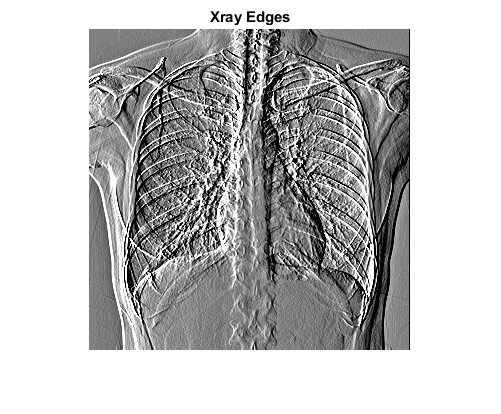

g1=conv2(f,edgex,'same');
imshow(g1,[-10,10]);
title('Xray Edges')

Los colores realizan el cambio de blanco a negro, por ello la imagen se observa de esa forma. 

edgey=[-1 -2 -1;0,0,0;1,2,1]/8

edgey =    -0.1250   -0.2500   -0.1250
         0         0         0
    0.1250    0.2500    0.1250


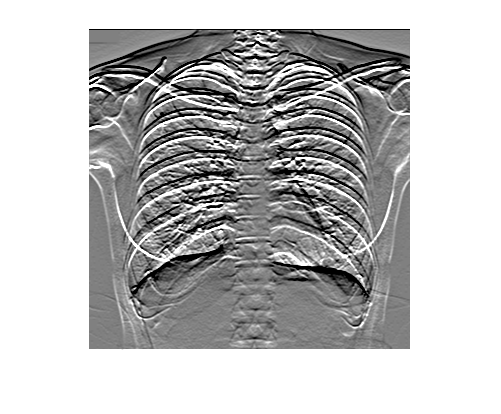

g2=conv2(f,edgey,'same');
imshow(g2,[-10,10])

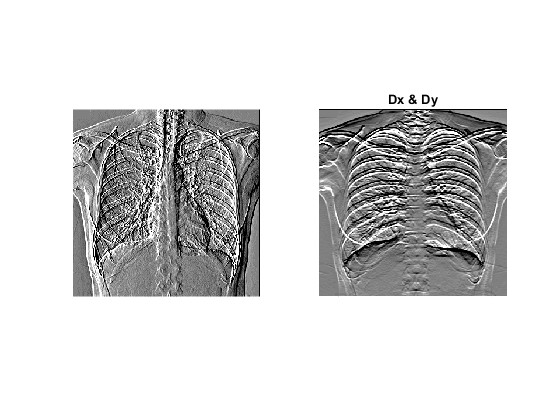

figure(2)
subplot(1,2,1)
imshow(g1,[-10,10])
subplot(1,2,2)
imshow(g2,[-10,10])
title('Dx & Dy')

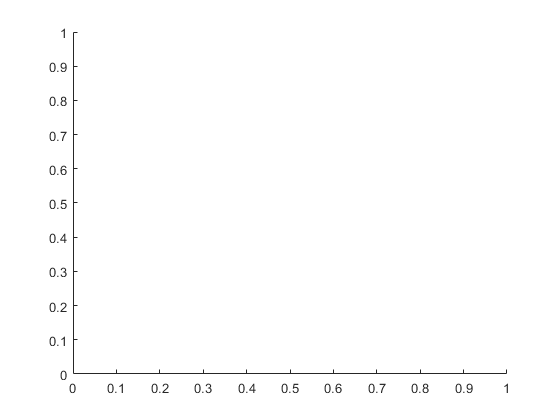

figure(3)
subplot(1,1,1)

edgex=[1,0,-1;2,0,-2;1,0,-1]/8

edgex =     0.1250         0   -0.1250
    0.2500         0   -0.2500
    0.1250         0   -0.1250


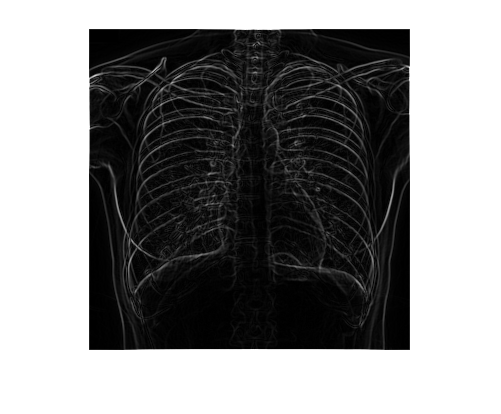

gx=conv2(f,edgex,'same');
gy=conv2(f,edgey,'same');
mag=abs(gx)+abs(gy);
imshow(mag,[]);

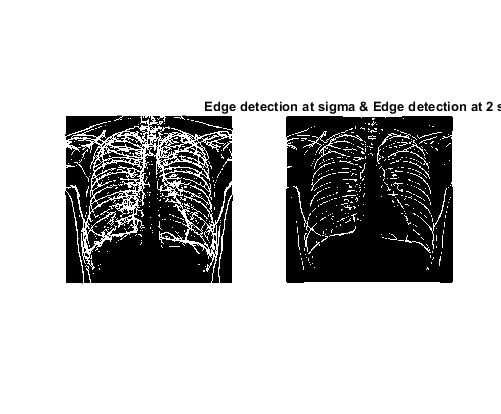

noisemask = [-1, 0 1];
noiseimage = conv2(f,noisemask,'same');
noisevariance = mean2(noiseimage.^2);
noisestd = sqrt(noisevariance/2);
edgedetection1 = mag > noisestd;
edgedetection2 = mag > 2*noisestd;
subplot(1,2,1)
imshow(edgedetection1,[]);
subplot(1,2,2)
imshow(edgedetection2,[]);
title('Edge detection at sigma & Edge detection at 2 sigma')

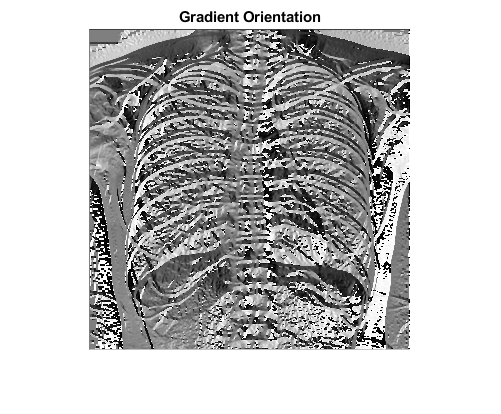

figure(4)
subplot(1,1,1)
angle=atan2(gy,gx);
imshow(angle,[]);
title('Gradient Orientation')

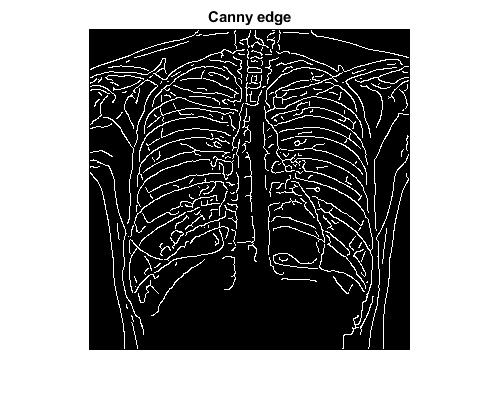

edgcany=edge(f,'Canny');
imshow(edgcany,[]);
title('Canny edge' ...
    )